# Algoritmos Numéricos por Computadora

# Examen final - Primavera 2024

Sube tu archivo resultado a Canvas $\to$ Examen final antes de las 18:45 horas.

**Aseguráte que tus resultados se despliegan en el archivo que subas. Los resultados deben aparecer abajo de las preguntas (en línea).**

**Al final del script debes incluir las funciones usadas para resolver las preguntas.**

**En cada gráfica, coloca etiquetas en los ejes, un grid, un título adecuado y, si es conveniente, una leyenda.**

Cada pregunta vale 5 puntos.

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. El artículo 29 del Reglamento de Alumnos establece que "se calificará como no acreditada (N.A.) cualquier materia cuando el alumno incurra en alguna práctica fraudulenta".

## 1. Aplicar métodos numéricos para resolver ecuaciones diferenciales. 

Utiliza RK4 y ABM4 (en su versión que guarda *todos* los valores calculados de f) para resolver el siguiente problema de valor inicial:

$y^{\prime } =\frac{-2y}{1+t}$         $y\;\left(0\right)=2$          t in [0,2.5]

a) Mide los tiempo de ejecución de cada método para $h={10}^{-3}$. Guarda los resultados (valores de $y$) en las variables $\textrm{yRK4}$ y $\textrm{yABM4}$.

f = @(t, y) (-2*y)/(1+t);
y0 = 2;
tspan = [0, 2.5];

tic
[tRK4, yRK4] = odeRK4(f, y0, tspan, 0.01);
toc
tic

Elapsed time is 0.031409 seconds.


[tABM4, yABM4] = ABM4(f, y0, tspan, 0.01);
toc

Elapsed time is 0.148007 seconds.


¿Cuál método es el más rápido? ¿Por qué?   

% ABM4, gracias a que solo evalua la funcion 2 veces en vez de 4

b) Grafica los resultados $y\left(t\right)$ obtenidos por los dos métodos.

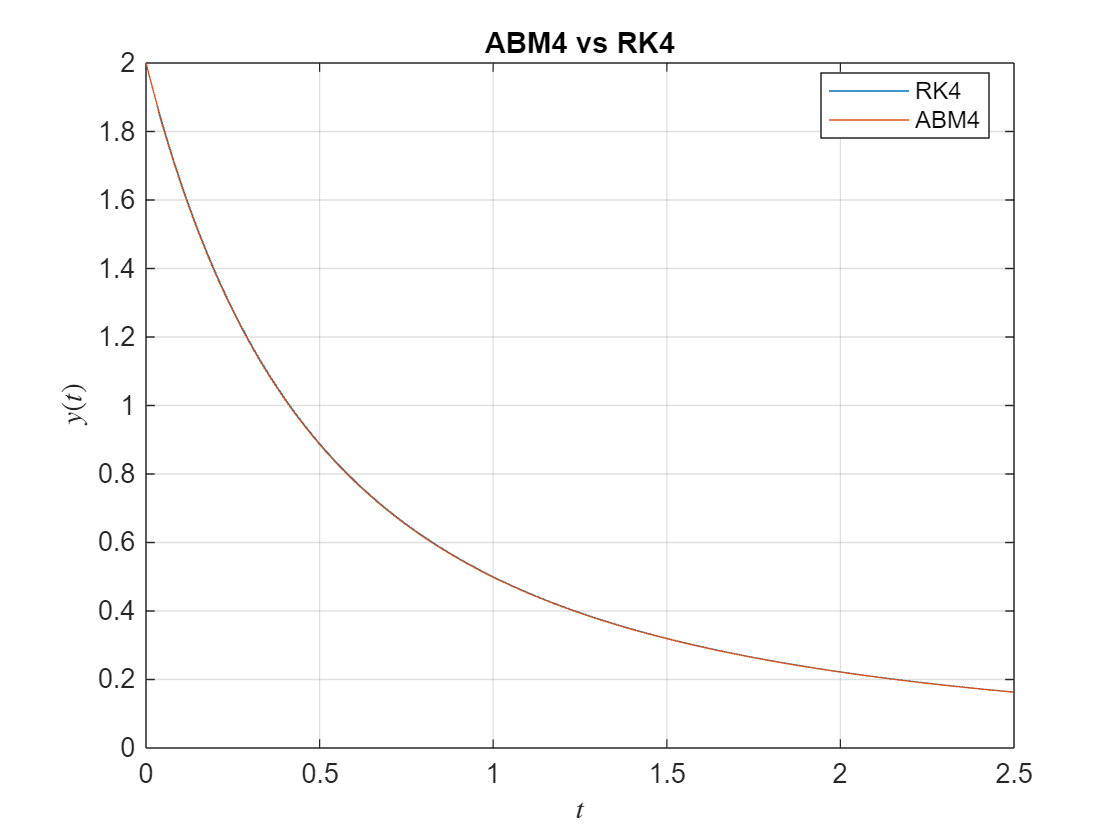

plot(tRK4, yRK4)
hold on
plot(tABM4, yABM4)
grid on
title('ABM4 vs RK4')
xlabel('$t$','interpreter','latex')
ylabel('$y(t)$','interpreter','latex')
legend('RK4', 'ABM4', 'location','best')
hold off

c) De manera simbólica, demuestra que la solución exacta es:


$$y\left(t\right)=\frac{2}{{\left(t+1\right)}^2 }$$


syms y(t) t
eqn = diff(y) == (-2*y)/(1+t);
cnd = y(0) == y0;
ysym = dsolve(eqn, cnd)

$$ysym = \frac{2}{{\left(t+1\right)}^{2}}$$

d) Grafica los errores absolutos de RK4 y ABM4 con respecto a la solución exacta.

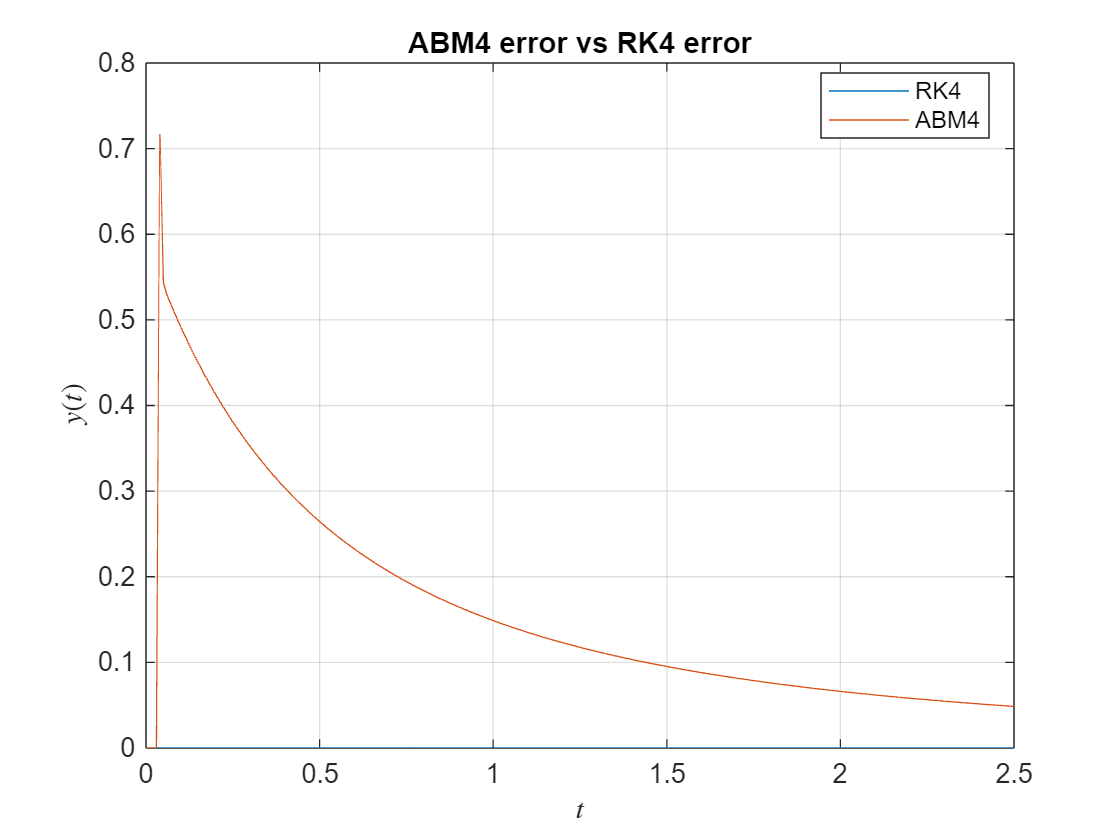

ysymVal = subs(ysym, t, tRK4);

plot(tRK4, abs(yRK4 - ysymVal)*100)
hold on
plot(tABM4, abs(yABM4 - ysymVal)*100)
grid on
title('ABM4 error vs RK4 error')
xlabel('$t$','interpreter','latex')
ylabel('$y(t)$','interpreter','latex')
legend('RK4', 'ABM4', 'location','best')
hold off

 ¿Qué método tiene más error? ¿De qué orden de magnitud son los errores? ¿Qué relación tienen con h?

% Ambos metodos son de orden de h^4, en este caso, ABM4 esta teniendo mas
% error probablemente por truncamiento mas que por redondeo, una h mas
% adecuada deberia solucionar el problema

e) Como el predictor y el corrector de ABM4 son del mismo orden, podemos estimar el error local de truncamiento en la iteración $i+1$ para el predictor $p$ y para el corrector $c$.

$E_p =\frac{251}{270}\left(c_i -p_i \right)$    y   $E_c =-\frac{19}{270}\left(c_{i+1} -p_{i+1} \right)$

Estos errores deben sumarse a los valores determinados por las fórmulas del predictor $p$ y del corrector $c$ en cada iteración para obtener los valores de $y_{i+1}$.

Escribe la función` [t,y] = ABM4m(f, y0, tsan, h) `que implemente estas modificaciones y compara, en un gráfica, los errores absolutos obtenidos con los de RK4.

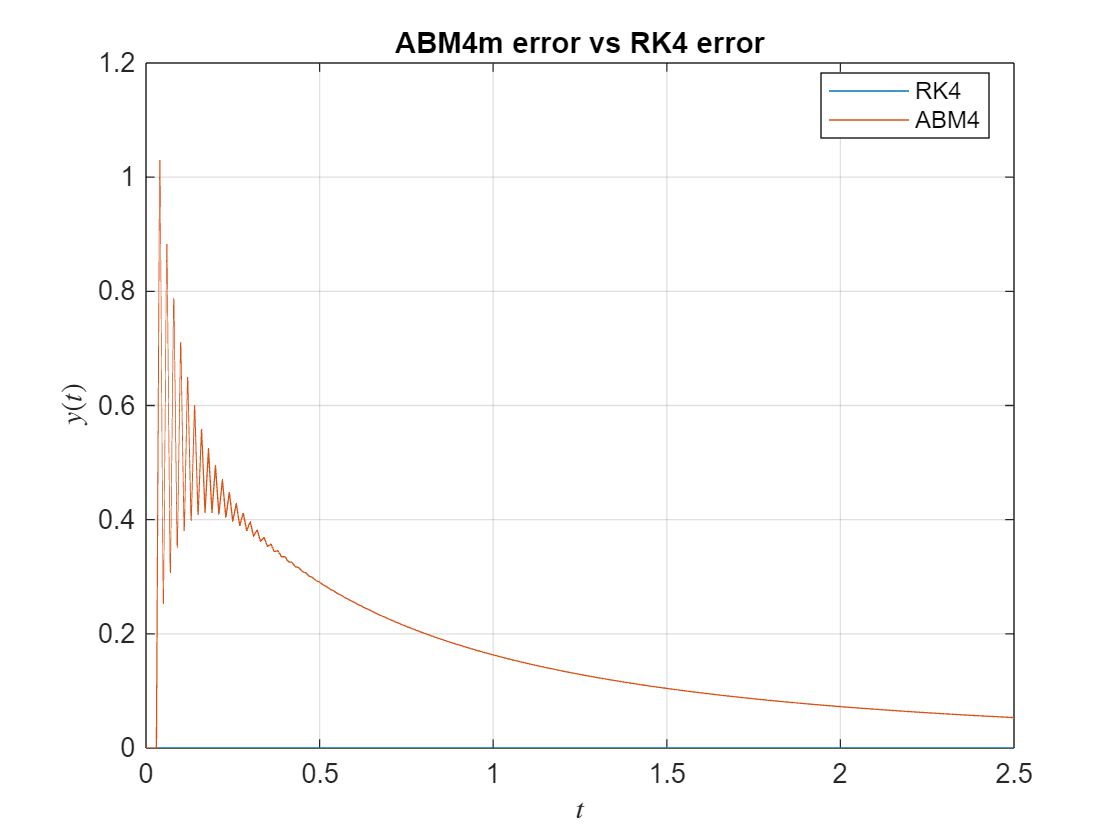

function [t, y] = ABM4m(f, y0, tspan, h)
    t = tspan(1):h:tspan(2);
    n = length(t);
    m = length(y0);
    y = zeros(m, n);
    y(:, 1) = y0;
    
    fv = zeros(m, n);
    [~, y(:, 1:4)] = odeRK4(f, y0, [t(1) t(4)], h);
    fv(:, 4) = bsxfun(f, t(1:4), y(:, 1:4));
    ci = 0; pi = 0;
    for i = 4:n-1
        yi = y(:, i);
        y(:, i+1) = yi + h/24*(55*fv(i) - 59*fv(i-1) + 37*fv(i-2) - 9*fv(i-3));
        fv(:, i+1) = f(t(i+1), y(:, i+1));
        y(:, i+1) = y(:, i+1) + 251/270*(ci - pi);
         
        pi = y(:, i+1);
        y(:, i+1) = yi + h/24*(9*fv(i+1) + 19*fv(i) - 5*fv(i-1) + fv(i-2));
        yi = y(:, i+1);
        y(:, i+1) = yi - 19/270*(yi - pi);
        fv(:, i+1) = f(t(i+1), y(:, i+1));
        ci = y(:, i+1);
    end
end

[tABM4, yABM4] = ABM4m(f, y0, tspan, 0.01);
plot(tRK4, abs(yRK4 - ysymVal)*100)
hold on
plot(tABM4, abs(yABM4 - ysymVal)*100)
grid on
title('ABM4m error vs RK4 error')
xlabel('$t$','interpreter','latex')
ylabel('$y(t)$','interpreter','latex')
legend('RK4', 'ABM4', 'location','best')
hold off

Debes observar que los errores de ABM4 se reducen fuertemente.

## 2. Analizar el funcionamiento de diversos métodos numéricos.

Escribe la función `[L,flag] = choleskyFlag(A)` que factoriza la matriz $A=L*L^{\prime }$ y que regresa también la variable entera `flag` que indica si la matriz $A$ es simétrica positiva definida. El ciclo del algoritmo de factorización debe terminar si se calcula un elemento diagonal que no sea real positivo (**no** puedes usar un for).

- Si `flag = 0` entonces la matriz es positiva definda y la factorización se realizó con éxito.

- Si `flag` no es cero, entonces la matriz no es positiva definda y `flag` indica la posición del pivote donde falló la factorización.

No puedes utilizar ninguna otra función, ni tuya ni de MATLAB, para determinar si la matriz $A$ es simétrica positiva definida.

Prueba la función con las siguientes matrices. Si la matriz es positiva definida, muestra que $A=L*L^{\prime }$.


$$A=\left\lbrack \begin{array}{ccc}
4 & 2 & 2\\
2 & 26 & 21\\
2 & 21 & 18
\end{array}\right\rbrack$$


A = [4 2 2;
    2 26 21;
    2 21 18];

[flag, L] = choleskyFlag(A);
% comprobacion
eigA = eig(A);
all(eigA > 0) && all(isreal(eigA))

ans = logical
   1


disp(flag)

   1



L*L'

ans =      4     2     2
     2    26    21
     2    21    18



$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
2 & 4 & 5\\
3 & 5 & 6
\end{array}\right\rbrack$$


A = [1 2 3;
     2 4 5;
     3 5 6];
[flag, L] = choleskyFlag(A);
% comprobacion
eigA = eig(A);
all(eigA > 0) && all(isreal(eigA))

ans = logical
   0


disp(flag)

   0



L*L'

ans =    1.0000 + 0.0000i   2.0000 + 0.0000i      NaN +    NaNi
   2.0000 + 0.0000i   4.0000 + 0.0000i      NaN +    NaNi
      NaN +    NaNi      NaN +    NaNi      Inf + 0.0000i


## 3. Entender los errores numéricos inherentes a las soluciones computacionales.

Resuelve la siguiente ecuación diferencial "stiff":


$${y\left(t\right)}^{\prime } =-1000y+3000-2000e^{-t}$$
         
$$y\;\left(0\right)=0$$
         

en el intervalo [0, 0.01]. 

a) El criterio de convergencia $h<\frac{2}{a}$ con ($\left.a=1000\right)$ indica que h debe ser menor a 0.002 para que el metodo de Euler sea estable. Utiliza el método de Euler con $h=0\ldotp 0025$ y grafica $y\left(t\right)$. 

f = @(t, y) -1000*y + 3000 - 2000*exp(-t);
h = 0.0025;
y0 = 0;
tspan = [0, 0.01];

[tEuler, yEuler] = odeEuler(f, y0, tspan, h);
plot(tEuler, yEuler)
hold on
grid on
title('Euler comparison')
xlabel('$t$','interpreter','latex')
ylabel('$y(t)$', 'interpreter', 'latex')

b) Si $\frac{2}{a}<h<\frac{1}{a}$ el metodo de Euler es estable pero presenta ocilaciones.Utiliza el método de Euler con $h=0\ldotp 0015$ y grafica $y\left(t\right)$. 

h = 0.0015;
[tEuler, yEuler] = odeEuler(f, y0, tspan, h);
plot(tEuler, yEuler)

c) Utiliza el método de Backward Euler con $h=0\ldotp 0025$ y grafica $y\left(t\right)$. Observa que la ecuación diferencial es lineal y utiliza una implementación **eficiente**.

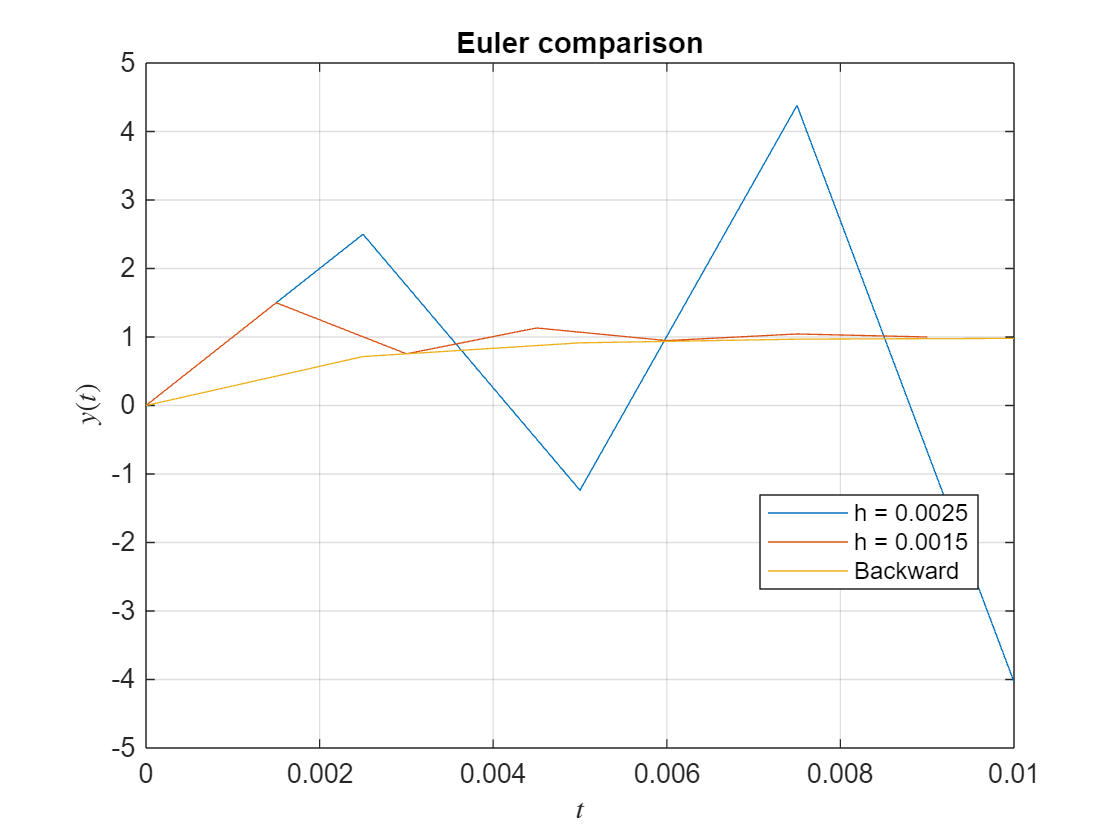

h = 0.0025;
g = @(t,y) (y + (3000 - 2000*exp(t))*h)/(1 + 1000*h);
[tEuler, yEuler] = odeEulerImplicito(g, y0, tspan, h);
plot(tEuler, yEuler)
legend('h = 0.0025', 'h = 0.0015','Backward', 'location', 'best')
hold off

## 4. Construir representaciones matemáticas de sistemas físicos.

Un saltador bungee a una altura inicial $z_0$ es lanzado hacia arriba a una velocidad inicial $v_0$.

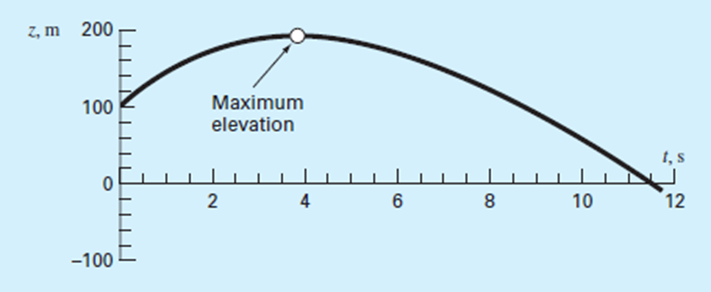

La fuerza que actua sobre el saltador es:


$$F=F_g +F_a$$


$F_g$ : fuerza debida a la gravedad = $-\;m\;g$

$F_a$ : fuerza debida a la resistencia del aire (fricción) = $-\;c\;v$

a) Utiliza la segunda ley de Newton $F=m\;a$ para demostrar que la ecuación diferencial (no homogenea) de segundo orden que determina la altura $z$ del saltador es:

$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }z$ +$\frac{c}{m}$ $\frac{\mathrm{d}}{\mathrm{d}t}z=-g$

% F - Fa = Fg
% ma - (-cv) = -mg
% a = d^2/dt^2 z    v = d/dt z
% m * d^2/dt^2 z + c * d/dt z = - mg
% d^2/dt^2 z + c/m * d/dt z = - g

b) Convierte esta ecuación en dos ecuaciones diferenciales de primer orden y resuelve el sistema en el intervalo $\textrm{tspan}=\left\lbrack 0\;10\right\rbrack$ usando RK4. Grafica $z\left(t\right)$. Utiliza los siguientes valores: $g=9\ldotp 81\frac{m}{s^2 }$,  $m=80\;\textrm{kg}$, $c=15\;\frac{\textrm{kg}}{c}$  (coeficiente lineal de arrastre), $z_0 =100\;m$ y $v_0 =55\frac{m}{s}$.

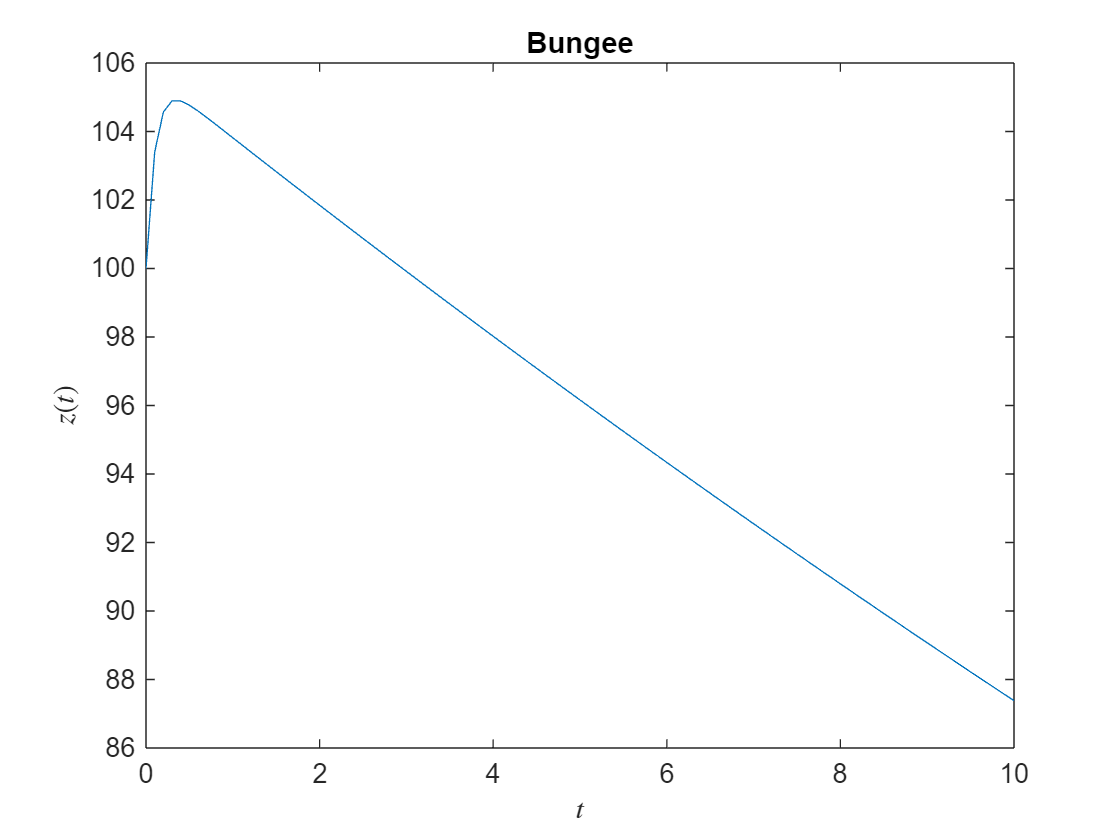

g = 9.81; m = 80; c = 15; z0 = 100; v0 = 55;
tspan = [0 10]; zv0 = [z0; v0];
M = [0 1; -c/m -g];
f = @(t, zv) M*zv;

[t, zv] = odeRK4(f, zv0, tspan, 0.1);
plot(t, zv(1, :))
title("Bungee")
xlabel("$t$", 'interpreter','latex')
ylabel("$z(t)$", 'interpreter','latex')

c) ¿Cuál es la altura máxima que alcanza? 

[zmax, tmax] = max(zv(1, :));
fprintf('La altura maxima es %f', zmax)

La altura maxima es 104.893363

¿En qué tiempo alcanza la altura máxima?

fprintf('En el tiempo %f', t(tmax))

En el tiempo 0.300000

d) Resuelve simbólicamente la ecuación diferencial de segundo orden

$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }z$ +$\frac{c}{m}$ $\frac{\mathrm{d}}{\mathrm{d}t}z=-g$

y demuestra que


$$z\left(t\right)=z_0 +\frac{m}{c}\left(v_0 +\frac{m\;g}{c}\right)\left(1+e^{-\frac{c}{m}t} \right)-\frac{m\;g}{c}t$$


syms z(t) m g c z0 v0
dz = diff(z);
eqn = diff(z, t, 2) + dz*c/m + g == 0;
cnd1 = z(0) == z0;
cnd2 = dz(0) == v0;
cnd = [cnd1 cnd2];
zsym = dsolve(eqn, cnd)

$$zsym = \frac{z_{0}\,c^{2}+v_{0}\,c\,m+g\,m^{2}}{c^{2}}-\frac{{\mathrm{e}}^{-\frac{c\,t}{m}}\,\left(g\,m^{2}+c\,v_{0}\,m\right)}{c^{2}}-\frac{g\,m\,t}{c}$$

e)  A partir de la solución exacta, determina ahora el tiempo exacto en el que el saltador alcanza la elevación *máxima* y la altura correspondiente.

gr = 9.81; mr = 80; cr = 15; z0r = 100; v0r = 55;
tspansym = 0:h:10;
zsymVal = subs(zsym, [m g c z0 v0], [gr mr cr z0r v0r]);
zsymVal = subs(zsymVal, t, tspansym);

[zmaxsym, tmaxsym] = max(zsymVal(1, :));
fprintf('La altura maxima es %f', zmaxsym)

La altura maxima es 111.387063

fprintf('En el tiempo %f', tspansym(tmaxsym))

En el tiempo 0.470000

## 5. Demostrar habilidad en el uso eficiente de MATLAB.

Escribe la función `[x,i,min]= NRoptimizacionVV(f,x) `para optimizar funciones de varias variables.  

Debes tener funciones **eficientes** para calcular, de manera numérica, el gradiente `del = gradiente(f, x)` y la hessiana H = `hessiana(f, x)` de la función. 

a) Grafica la función $f\left(x,y\right)=2\;x\;y+2x-x^2 -2y^2$ en $-1\le x\le 3$, $-1\le y\le 3$. Puedes utilizar la función `mesh` de MATLAB.

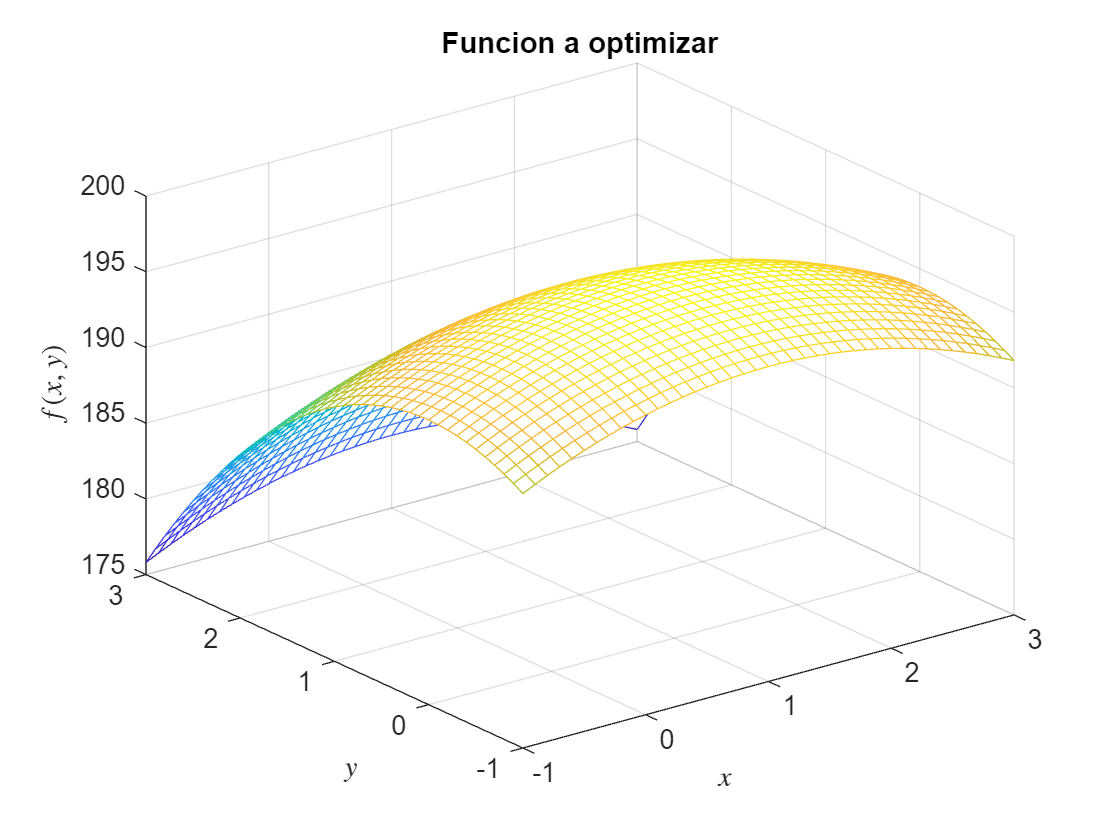

f = @(x, y) 2*x*y + 2*x - x.^2 - 2.*y.^2;
[x, y] = meshgrid(-1:0.1:3);
mesh(x, y, f(x, y))
title('Funcion a optimizar')
xlabel('$x$','interpreter','latex')
ylabel('$y$','interpreter','latex')
zlabel('$f(x,y)$','interpreter','latex')

b) Encuentra el valor $\left(x,y\right)$ donde ocurre el máximo de la función $f\left(x,y\right)=2\;x\;y+2x-x^2 -2y^2$ y el valor de este máximo, utilizando la función `NRoptimizacionVV(f,x)e` iniciando en $\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$.

xy0 = [0; 0];
g = @(u) -(2*u(1)*u(2) + 2*u(1) - u(1).^2 - 2.*u(2).^2);
[x, i, max] = NRoptimizacionVV(g, xy0);
fprintf('Valor maximo de x - %f y de y - %f', x(1), x(2))

Valor maximo de x - 194.104280 y de y - -28.448257

fprintf('Valor maximo de f - %f', max)

Valor maximo de f - 49950.726809

## Funciones

`[t,y] = ABM4m(f, y0, tsan, h) `

function [t, y] = ABM4(f, y0, tspan, h)
    t = tspan(1):h:tspan(2);
    n = length(t);
    m = length(y0);
    y = zeros(m, n);
    y(:, 1) = y0;
    
    fv = zeros(m, n);
    [~, y(:, 1:4)] = odeRK4(f, y0, [t(1) t(4)], h);
    fv(:, 4) = bsxfun(f, t(1:4), y(:, 1:4));
    for i = 4:n-1
        yi = y(:, i);
        y(:, i+1) = yi + h/24*(55*fv(i) - 59*fv(i-1) + 37*fv(i-2) - 9*fv(i-3));
        fv(:, i+1) = f(t(i+1), y(:, i+1));
        
        y(:, i+1) = yi + h/24*(9*fv(i+1) + 19*fv(i) - 5*fv(i-1) + fv(i-2));
        fv(:, i+1) = f(t(i+1), y(:, i+1));
    end
end

`[L,flag] = choleskyFlag(A)` 

function [flag, L] = choleskyFlag(A)
    flag = true;
    if ~issymmetric(A), flag = false; end
    n = length(A);

    L = zeros(n, n);
    L(1, 1) = sqrt(A(1, 1));
    L(:, 1) = A(:, 1)/L(1, 1);

    for i = 2:n-1
        L(i, i) = sqrt(A(i, i) - L(i, 1:i-1).^2);
    end
    
    for j = 2:n-1
        for i = j+1:n
            L(i, j) = (A(i, j) - L(i, 1:j-1)*L(j, 1:j-1)')/L(j, j);
        end
    end

    L(n, n) = sqrt(A(n, n) - sum(L(n, 1:n-1).^2));
    
    if ~(isreal(diag(L))), flag = false; end
end


`[x,i,min]= NRoptimizacionVV(f,x)`

function [x, i, min] = NRoptimizacionVV(f, x0, rTol, itMax)
    if ~exist("rTol", "var"), rTol = nthroot(eps, 3); end
    if ~exist("itMax", "var"), itMax = 1000; end
    
    x = x0 - hessiana(f, x0)\gradiente(f, x0);
    i = 0;
    condition = true;
    while condition
        xP = x;
        x = xP - hessiana(f, xP)\gradiente(f, xP);
        
        i = i + 1;
        condition = norm((x - xP)./x, inf) > rTol && i < itMax;
    end
    min = f(x);
end

del = gradiente(f, x)

function del = gradiente(f, x)
    h = nthroot(eps, 3);
    n = length(x);
    dx = h*eye(n);
    del = zeros(n, 1);
    
    for i = 1:n
        del(i) = (f(x(i) + dx(:, i)) - f(x(i) - dx(:, i)))/(2*h);
    end
end

H = hessiana(f, x)

function H = hessiana(f, x)
    n = length(x);
    h = nthroot(eps, 3);
    
    dx = eye(n)*h;
    dfx = diag(x);
    H = zeros(n, n);
    for i = 1:n
        for j = 1:n
            if i == j, H(i, i) = (f(x + dx(:, i)) - 2*f(x) + f(x - dx(:, i)))/h^2;
            else
                temp = (f(dfx(:, j) + dx(:, j)) - f(dfx(:, j) - dx(:, j)))/(2*h);
                H(i, j) = temp;
            end
        end
    end
end

Otras funciones

function [t, y] = odeRK4(f, y0, tspan, h)
    t = tspan(1):h:tspan(2);
    n = length(t);
    y = zeros(length(y0), n);

    y(:, 1) = y0;
    for i = 1:n-1
        ti = t(i);
        yi = y(:, i);
        k1 = f(ti, yi);
        k2 = f(ti + 1/2*h, yi + 1/2*k1*h);
        k3 = f(ti + 1/2*h, yi + 1/2*k2*h);
        k4 = f(ti + h, yi + k3*h);

        y(:, i+1) = yi + 1/6*(k1 + 2*k2 + 2*k3 + k4)*h;
    end
end

function [t, y] = odeEuler(f, y0, tspan, h)
    t0 = tspan(1);
    tn = tspan(2);
    
    t = t0:h:tn;
    n = length(t);
    y = zeros(length(y0), n);
    y(:, 1) = y0;
    for i = 1:n-1
        phi = f(t(i), y(:, i));
        y(:, i+1) = y(:, i) + phi*h;
    end
end

function [t, y] = odeEulerImplicito(f, y0, tspan, h)
    t = tspan(1):h:tspan(2);
    n = length(t);
    y = zeros(1, n);
    y(1) = y0;
        
    for i = 1:n-1
        y(i+1) = f(t(i), y(i));
    end
end
